% The steps of the project

% 1. Face Detection: Use face detection algorithms to find the face within the image.
% 2. Feature Detection: Apply feature detection algorithms to locate the eyes and mouth.
% 3. Geometric Transformation: Apply transformations to rotate, scale, and translate the image so that the eyes (and if possible, the mouth) are aligned to a standard template.
% 4. Cropping and Resizing: Crop the aligned face to a standard size and resize it if necessary.
% 5. PCA and Eigenface Generation: Once the images are normalized and aligned, proceed with PCA and eigenface generation as you've already done.
% 6. Recognition: When a new image is received, apply the same preprocessing steps to it before projecting it onto the eigenface space for recognition.

addpath('functions');

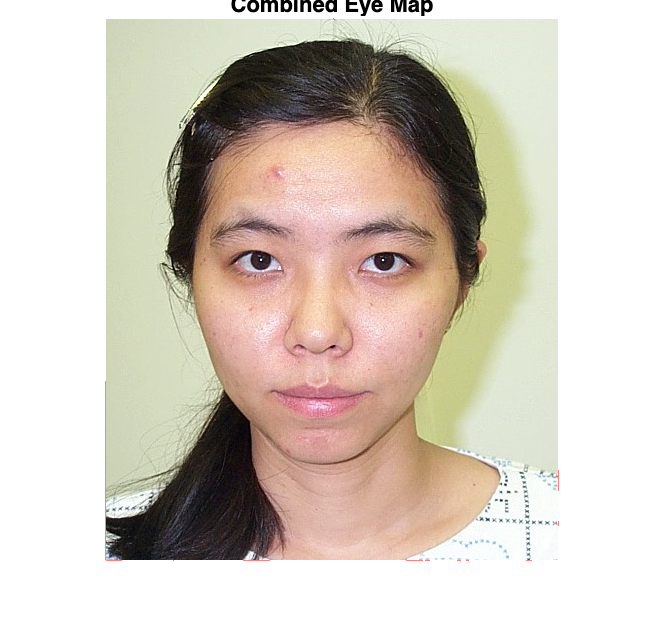

% 1. Color Space Conversion:
% Faces generally have a distinct color range that can be 
% more easily separated in color spaces like YCbCr or HSV 
% rather than RGB.
image = imread('images/DB1/db1_16.jpg');
imshow(image);


% EyeMap_combined = illumination_based_method(image);

sobel_eye_image = sobel_eye_detection(image, 100, 0.8);

insertShape requires Computer Vision Toolbox.

Error in sobel_eye_detection (line 17)
        final_image = insertShape(final_image, 'Rectangle', eyeCandidates(k).BoundingBox, 'Color', 'red', 'LineWidth', 2);

imshow(sobel_eye);

% Display the result
% imshow(EyeMap_combined);
% title('Combined Eye Map');

addpath('functions');

% Parameters
numImages = 16;
commonSize = [400, 300];
folderPath = 'images/DB1';
threshold = 0.90;  % Threshold for variance explanation

% Load and preprocess images
[dataMatrix, imageFiles] = loadAndPreprocessImages(folderPath, commonSize);

% Perform PCA
[score, meanFace, numEigenfaces, eigenfaces, numComponentsRequired] = performPCA(dataMatrix, threshold);

% Display number of components required
fprintf('Number of principal components needed: %d\n', numComponentsRequired);

% Project query image onto eigenfaces
queryImagePath = 'images/DB1/db1_02.jpg';
queryWeights = projectOntoEigenfaces(queryImagePath, eigenfaces, meanFace, commonSize);

% Recognize the face
recognizeFace(queryWeights, score, numImages, folderPath, imageFiles, numEigenfaces);

% Assuming 'image' is the original RGB image and 'EyeMap_combined' is the eye map

% Convert the original image back to RGB for display purposes
image_rgb = ycbcr2rgb(image);

% Find the coordinates of the two highest values
% This assumes you are looking for two eyes
[sortedValues, sortIndex] = sort(EyeMap_combined(:), 'descend');
maxIndex = sortIndex(1:2); % take the first two indices of the sorted values

% Convert the indices to 2D coordinates
[maxY, maxX] = ind2sub(size(EyeMap_combined), maxIndex);

% Draw red dots on the original image
% Create a copy of the original image to overlay the dots
image_with_dots = image_rgb;

% Define the color and size of the dots
dotColor = uint8([255 0 0]); % Red color
dotSize = 10; % Size of the dot radius

% Overlay the dots on the image
for i = 1:length(maxY)
    image_with_dots(maxY(i)-dotSize:maxY(i)+dotSize, maxX(i)-dotSize:maxX(i)+dotSize, :) = repmat(reshape(dotColor, 1, 1, []), [dotSize*2+1, dotSize*2+1, 1]);
end

% Display the result
imshow(image_with_dots);
title('Image with Red Dots on Eyes');